# Deaf bats videos: analysis of bat distance

Path2Data='/Volumes/server_home-1/users/JulieE/DeafSalineGroup151/';
PositionFoodBowl = [844 918 500 580]; % the model often classify the food bowl as a bat....

% Load the data from 1 date
Date = '20200124';
Path2res = fullfile(Path2Data, Date, 'video', 'inference', 'bat_detections.csv')

Path2res = '/Volumes/server_home-1/users/JulieE/DeafSalineGroup151/20200124/video/inference/bat_detections.csv'

opts = detectImportOptions(Path2res);
preview(Path2res,opts)

ans = 8×12 table
    Var1      date        view      frame     xmin      ymin      xmax      ymax     confidence    class    vidID                                                path                                            
    ____    ________    ________    _____    ______    ______    ______    ______    __________    _____    _____    ____________________________________________________________________________________________

     0      2.02e+07    {'Cam1'}      1      287.98     319.1     362.7    424.21     0.81593        0        1      {'X:/users/JulieE/DeafSalineGroup151\

Res = readtable(Path2res);
size(Res)

ans =       179188          12


Res(1:10,:)

ans = 10×12 table
    Var1      date        view      frame     xmin      ymin      xmax      ymax     confidence    class    vidID                                                path                                            
    ____    ________    ________    _____    ______    ______    ______    ______    __________    _____    _____    ____________________________________________________________________________________________

     0      2.02e+07    {'Cam1'}      1      287.98     319.1     362.7    424.21     0.81593        0        1      {'X:/users/JulieE/DeafSalineGroup151

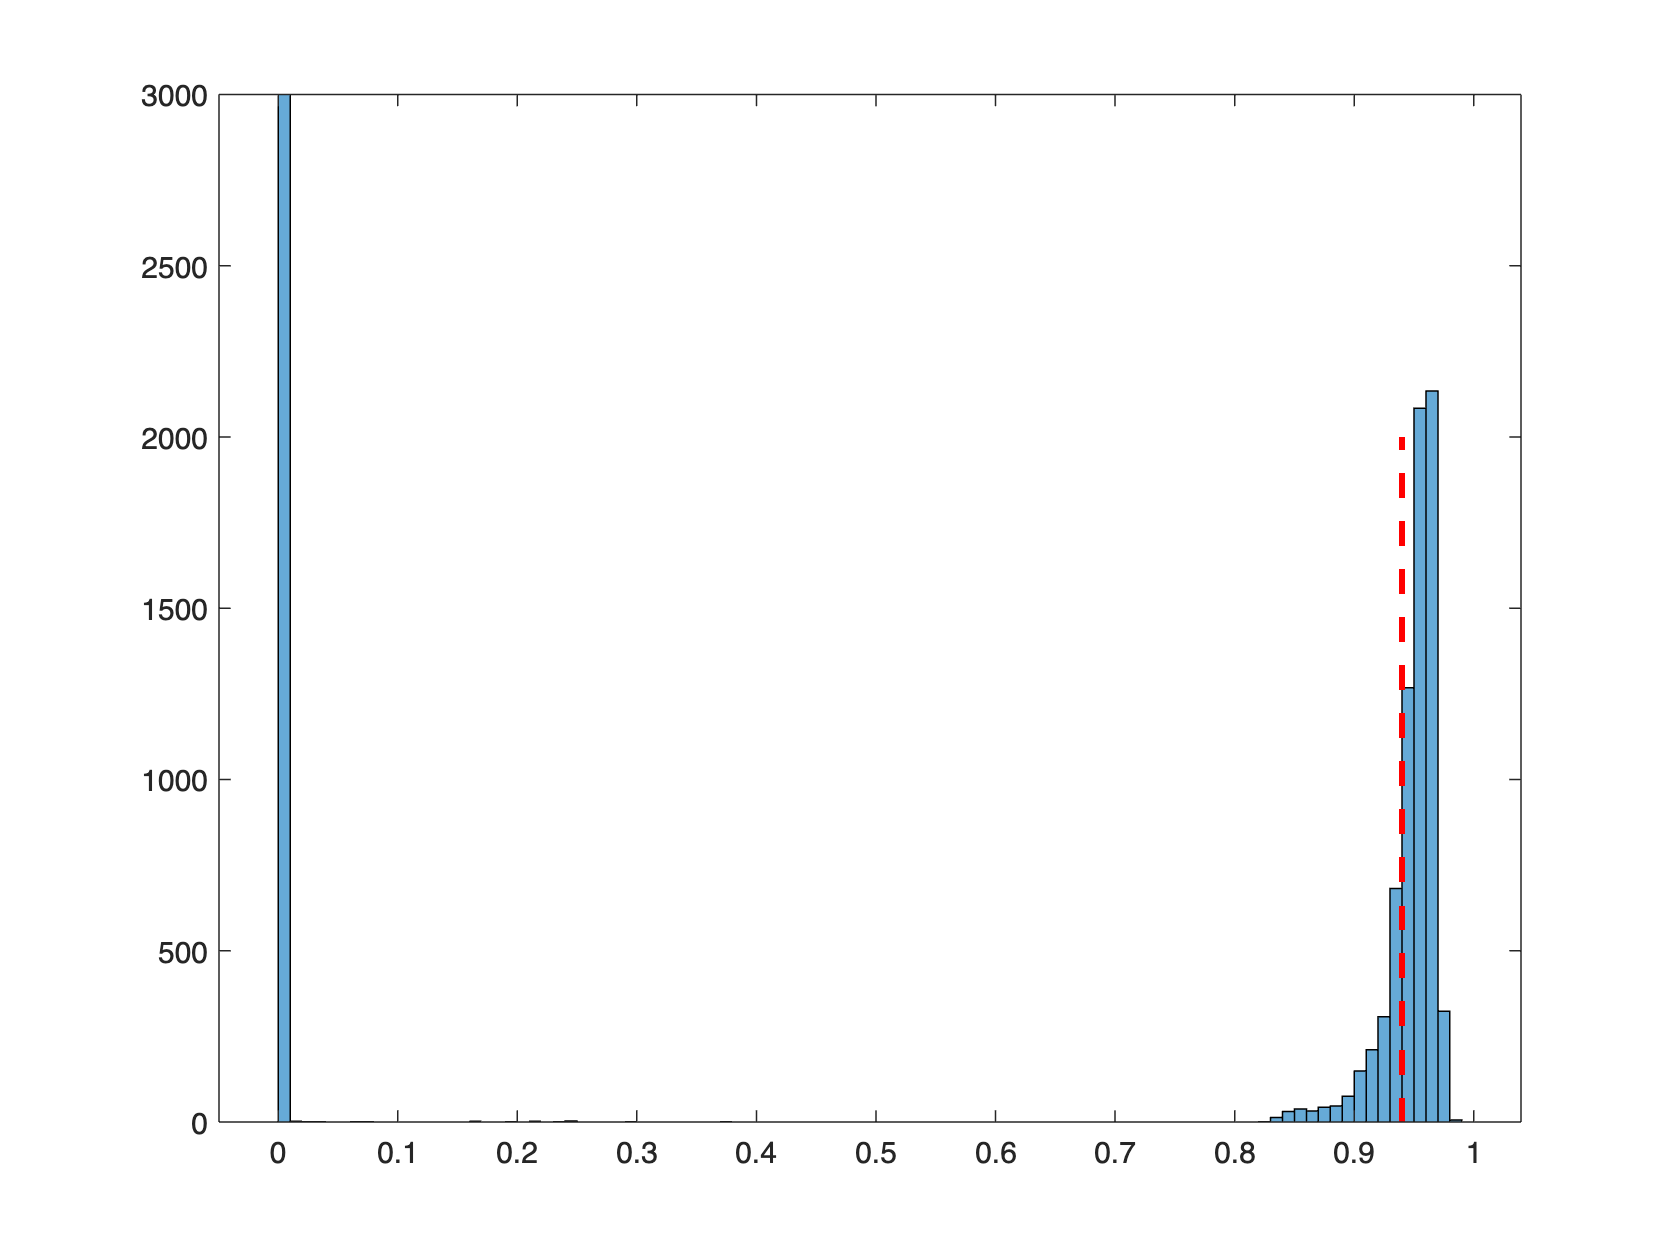

% Identify detections that wrongly correspond to the fruit bowl
ProportionOverlapped = nan(size(Res,1),1);
for rr=1:size(Res,1)
    OverlappingX = (min(Res.xmax(rr), PositionFoodBowl(2)) - max(Res.xmin(rr), PositionFoodBowl(1)));
    OverlappingY = (min(Res.ymax(rr), PositionFoodBowl(4)) - max(Res.ymin(rr), PositionFoodBowl(3)));
    if OverlappingX>0 && OverlappingY>0
        AreaOverlapped = OverlappingX * OverlappingY;
        TotAreas = (Res.xmax(rr) - Res.xmin(rr)) * (Res.ymax(rr) - Res.ymin(rr)) + (PositionFoodBowl(2) - PositionFoodBowl(1))*(PositionFoodBowl(4) - PositionFoodBowl(3));
        ProportionOverlapped(rr) = AreaOverlapped / (TotAreas - AreaOverlapped);
    else
        ProportionOverlapped(rr) = 0;
    end

end
histogram(ProportionOverlapped)
ylim([0 3000])
hold on; plot([0.94 0.94], [0 2000], 'r--', 'LineWidth',2); hold off

% Example of known false identification: ( check aga these values once
% inference is run
ProportionOverlapped(logical((Res.frame == 61) .* (Res.vidID==16)))

ans =          0
         0
         0
         0
         0
         0
         0
         0
    0.9525


ProportionOverlapped(logical((Res.frame == 5971) .* (Res.vidID==65)))

ans =          0
         0
         0
         0
         0
         0
    0.9477
         0


ProportionOverlapped(logical((Res.frame == 5851) .* (Res.vidID==47)))

ans =      0
     0
     0
     0


ProportionOverlapped(logical((Res.frame == 7501) .* (Res.vidID==38)))

ans =          0
         0
         0
         0
    0.9553
         0
         0
         0


ProportionOverlapped(logical((Res.frame == 5431) .* (Res.vidID==62)))

ans =          0
         0
         0
    0.9710


ProportionOverlapped(logical((Res.frame == 6541) .* (Res.vidID==55)))

ans =          0
         0
         0
         0
    0.9642
         0


% Do all of the frame with effectively correspond to Camera 1?
unique(Res.view(ProportionOverlapped>0.94))

ans = 1×1 cell array
    {'Cam1'}


% Yes :-)
sum(strcmp(Res.view(ProportionOverlapped>0.94), 'Cam1'))

ans = 5815

sum(strcmp(Res.view(ProportionOverlapped>0.94), 'Cam2'))

ans = 0

% Set the limit to 0.94. Everything above that value in overlap is
% considered a miss detection of the fruit bowl
GoodD01 = ProportionOverlapped<=0.94;
Res = Res(GoodD01,:);

% average size of detected bats (body width, body height) on camera 1
Body_width(1) = mean(Res.xmax(strcmp(Res.view, 'Cam1')) - Res.xmin(strcmp(Res.view, 'Cam1')));
Body_width(2) = std(Res.xmax(strcmp(Res.view, 'Cam1')) - Res.xmin(strcmp(Res.view, 'Cam1')));
Body_height(1) = mean(Res.ymax(strcmp(Res.view, 'Cam1')) - Res.ymin(strcmp(Res.view, 'Cam1')));
Body_height(2) = std(Res.ymax(strcmp(Res.view, 'Cam1')) - Res.ymin(strcmp(Res.view, 'Cam1')));
fprintf('average body width in pixels (mean std): %.2f +/- %.4f\naverage body height in pixels (mean std): %.2f +/- %.2f\n', Body_width(1), Body_width(2), Body_height(1), Body_height(2))

average body width in pixels (mean std): 51.51 +/- 16.3530
average body height in pixels (mean std): 104.90 +/- 20.75


% get the number of frames
UFrame = unique(Res.frame);
NFrame = length(UFrame);

% for camera 1 and each video and each frame, find the distance of each detected bat to the closest detected bats
UVid = unique(Res.vidID(strcmp(Res.view, 'Cam1'),:));
NVid = length(UVid);
Dist = cell(1, NFrame*NVid);
for vv=1:length(UVid)
    for ff=1:NFrame
        Detect_01 = logical((Res.frame == UFrame(ff)) .* (Res.vidID == UVid(vv)));
        Dist{NFrame*vv-1+ff} = nan(1, sum(Detect_01));
        Res_local = Res(Detect_01,:);
        for dd1 = 1:sum(Detect_01)
            Dist_local = nan(sum(Detect_01),1);
            Cdd1 = [Res_local.xmin(dd1) + (Res_local.xmax(dd1) - Res_local.xmin(dd1))/2 , Res_local.ymin(dd1) + (Res_local.ymax(dd1) - Res_local.ymin(dd1))/2];
            for dd2 = 1 : sum(Detect_01)
                if dd2==dd1
                    continue
                end
                Cdd2 = [Res_local.xmin(dd2) + (Res_local.xmax(dd2) - Res_local.xmin(dd2))/2 , Res_local.ymin(dd2) + (Res_local.ymax(dd2) - Res_local.ymin(dd2))/2];
                Dist_local(dd2) = ((Cdd1(1) - Cdd2(1))^2 + (Cdd1(2) - Cdd2(2))^2)^0.5;
            end
            Dist{NFrame*vv-1+ff}(dd1) = min(Dist_local);
        end
    end
end

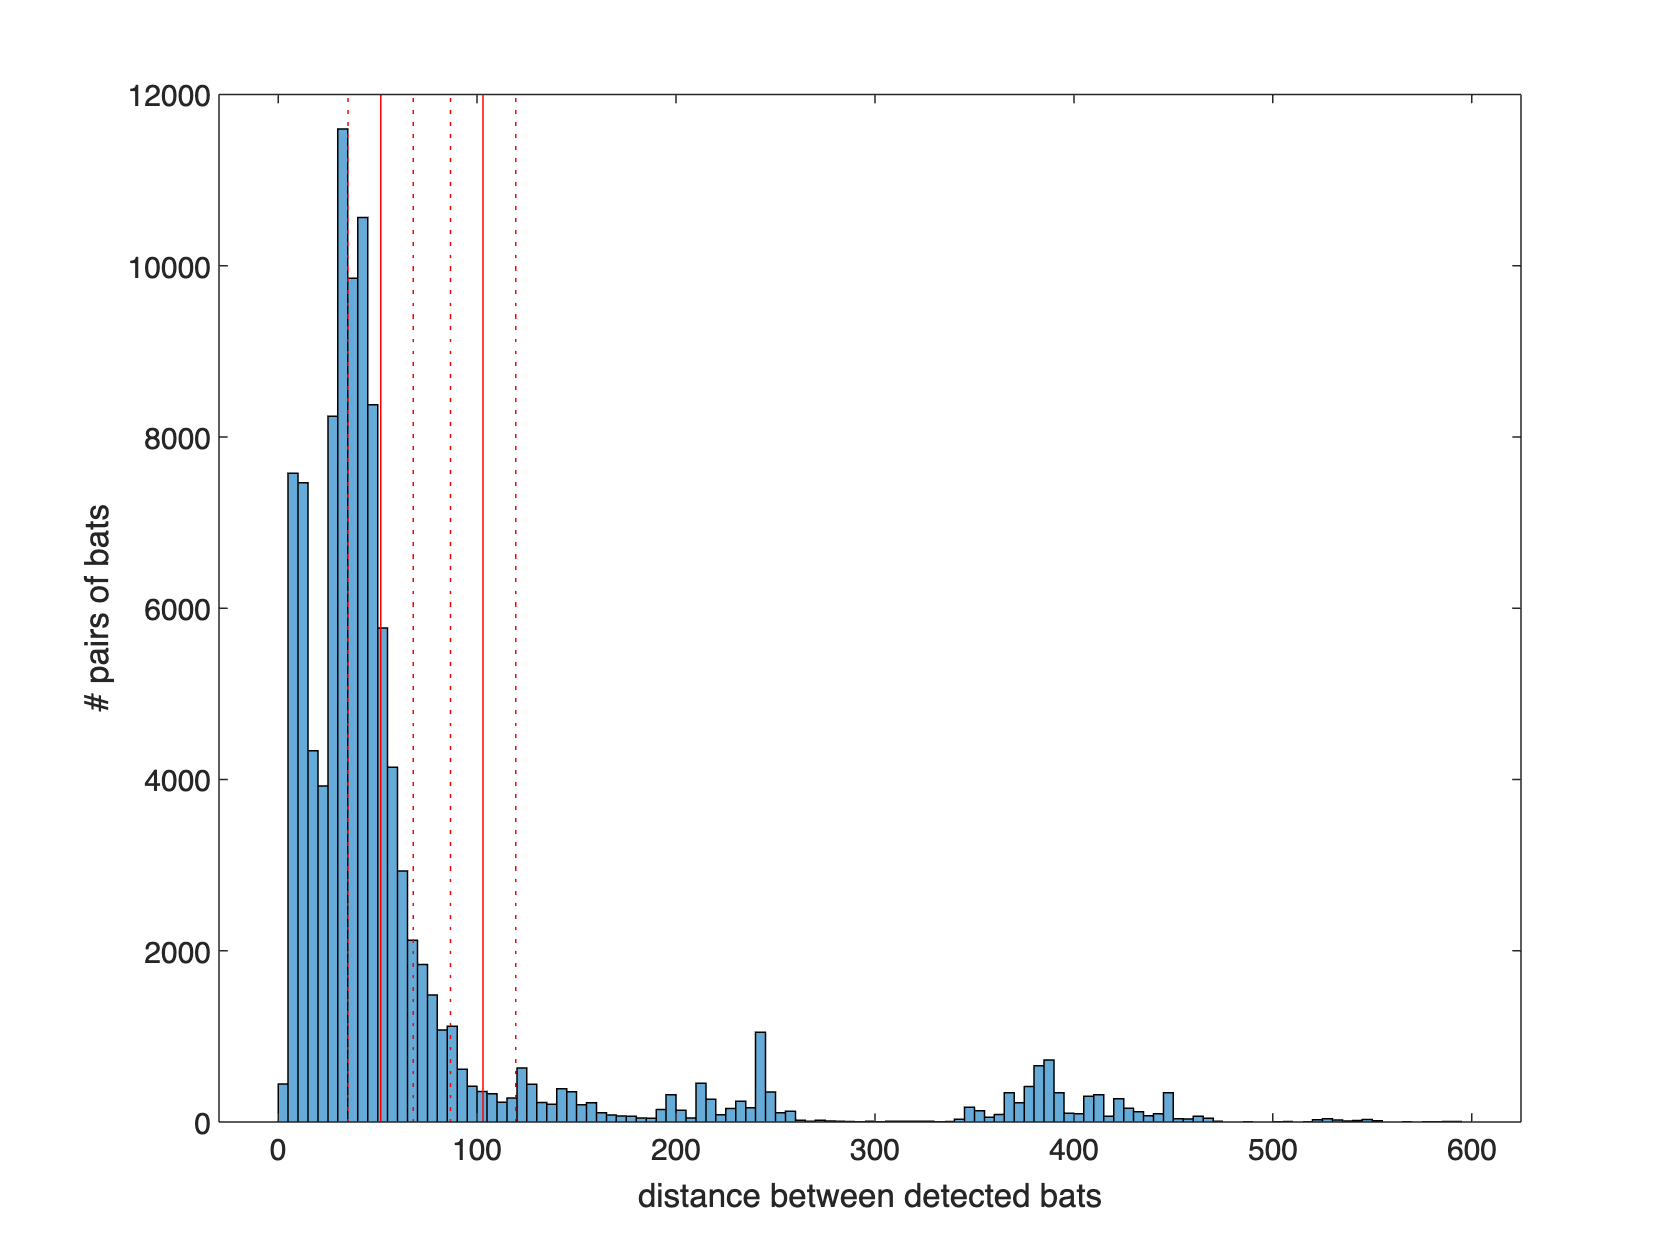

histogram([Dist{:}])
ylabel('# pairs of bats')
xlabel('distance between detected bats')
hold on; vline(Body_width(1), 'r-'); vline(Body_width(1)-Body_width(2), 'r:'); vline(Body_width(1)+Body_width(2), 'r:'); vline(2*Body_width(1), 'r-');vline(2*Body_width(1)-Body_width(2), 'r:'); vline(2*Body_width(1)+Body_width(2), 'r:'); hold off

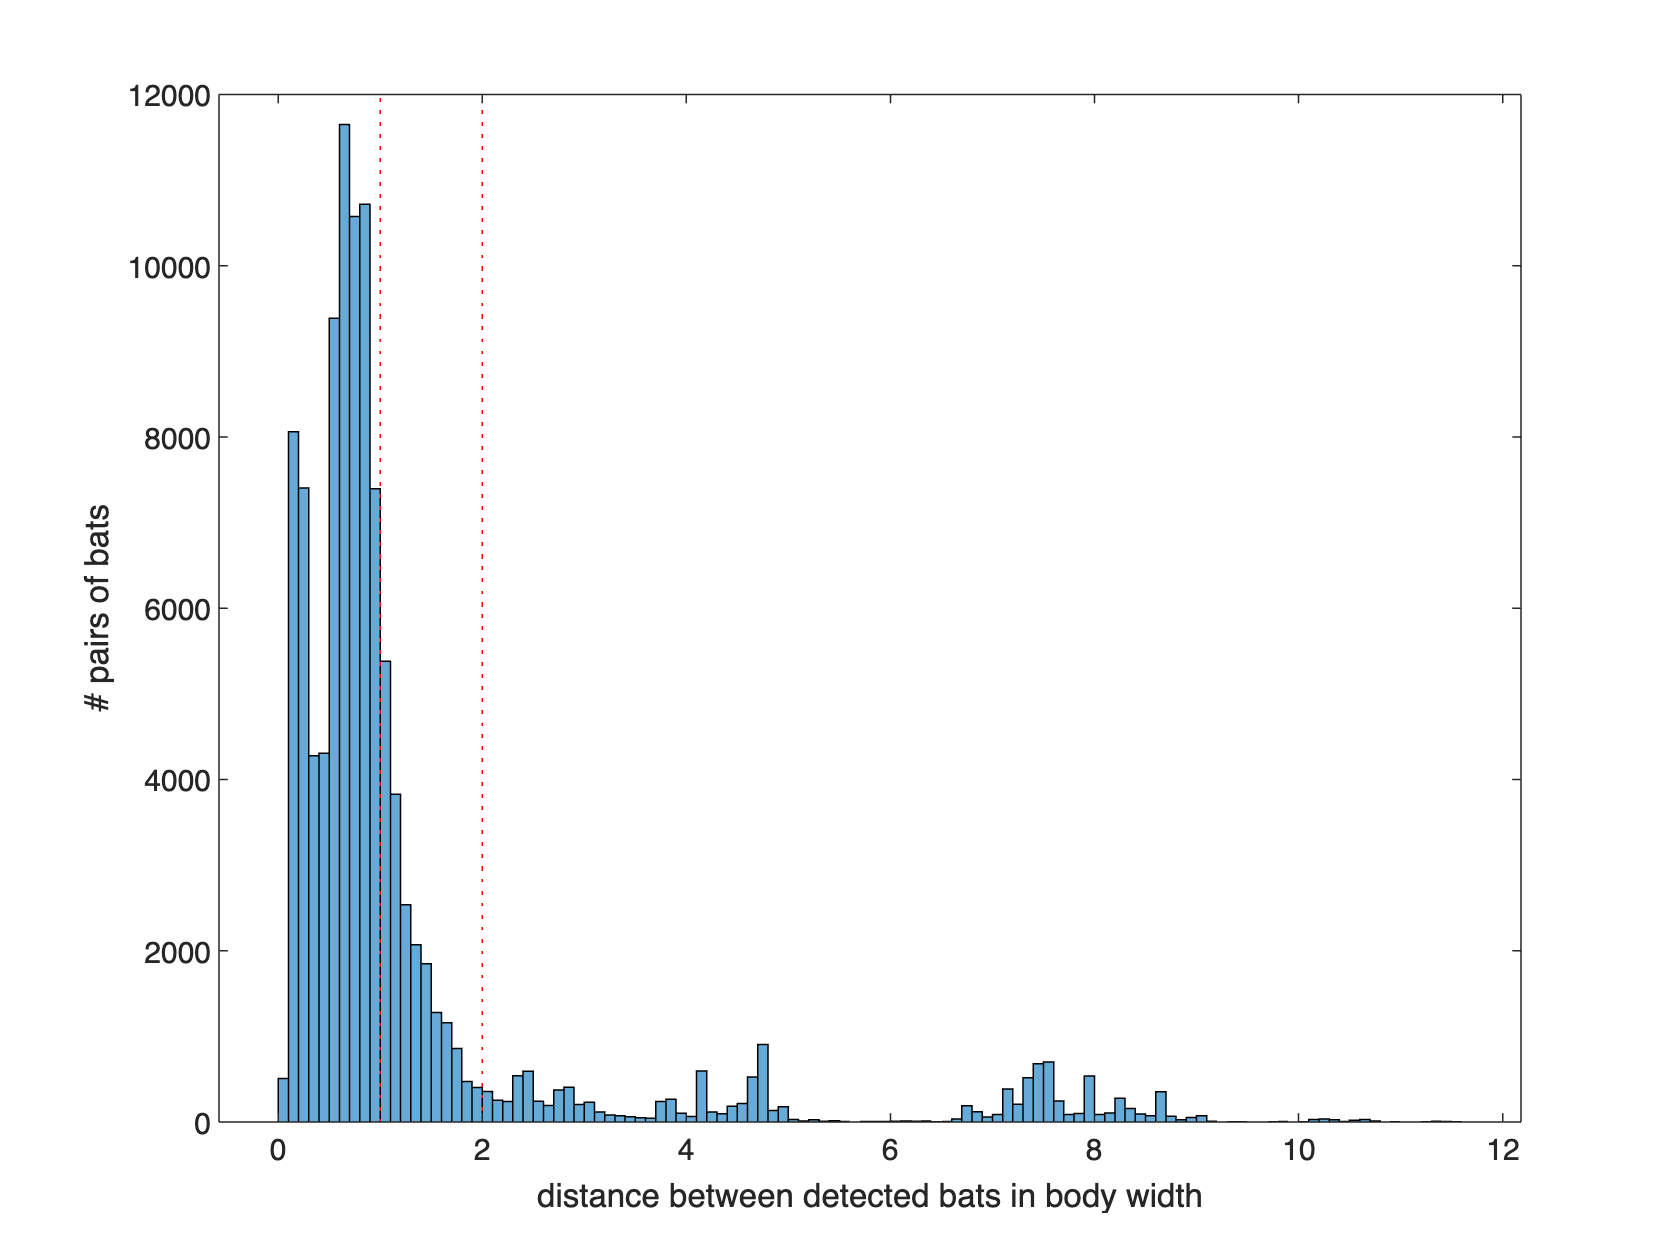

histogram([Dist{:}]./Body_width(1))
ylabel('# pairs of bats')
xlabel('distance between detected bats in body width')
hold on; vline(1); hold on; vline(2); hold off

I decide on a threshold to consider bats within the same cluster as mean body width + std

T = Body_width(1) + Body_width(2);

Now group bats by cluster on each frame

UVid = unique(Res.vidID(strcmp(Res.view, 'Cam1'),:));
NVid = length(UVid);
Clust = cell(1, NFrame*NVid); % for each frame the length of the vector is the number of bat cluster and the value the number of detected bats in the cluster
EmptyFrames = 0;
for vv=1:length(UVid)
    for ff=1:NFrame
        Detect_01 = logical((Res.frame == UFrame(ff)) .* (Res.vidID == UVid(vv)));
        Detect_cluster = 1:sum(Detect_01); % cluster # for each bat detection initialize with a different cluster for each
        Res_local = Res(Detect_01,:);
        if isempty(Res_local) % no data for this frame?
            EmptyFrames = EmptyFrames+1;
        end
        Dist_local = nan(sum(Detect_01),sum(Detect_01));
        for dd1 = 1:sum(Detect_01)
            Cdd1 = [Res_local.xmin(dd1) + (Res_local.xmax(dd1) - Res_local.xmin(dd1))/2 , Res_local.ymin(dd1) + (Res_local.ymax(dd1) - Res_local.ymin(dd1))/2];
            for dd2 = 1 : sum(Detect_01)
                if dd2==dd1
                    continue
                end
                Cdd2 = [Res_local.xmin(dd2) + (Res_local.xmax(dd2) - Res_local.xmin(dd2))/2 , Res_local.ymin(dd2) + (Res_local.ymax(dd2) - Res_local.ymin(dd2))/2];
                Dist_local(dd1,dd2) = ((Cdd1(1) - Cdd2(1))^2 + (Cdd1(2) - Cdd2(2))^2)^0.5;
            end
        end
        Dist_local2 = Dist_local;
        while sum(isnan(Dist_local2), 'All')<numel(Dist_local2)
            [Min,Imin] = min(Dist_local2, [], 'All', 'Linear');
            if Min<=T % these two bats belong to the same cluster
                [dd1, dd2] = ind2sub(size(Dist_local),Imin);
                ClustID_local = min(Detect_cluster(dd1), Detect_cluster(dd2));
                % group all bats that currently belong to these 2 cluster #
                Detect_cluster(Detect_cluster == Detect_cluster(dd1)) = ClustID_local;
                Detect_cluster(Detect_cluster == Detect_cluster(dd2)) = ClustID_local;
            else 
                % no bat is closer than T
                break
            end
            Dist_local2(dd1, dd2) = nan;
            Dist_local2(dd2, dd1) = nan;
        end
        Clusters = unique(Detect_cluster);
        for cc=1:length(Clusters)
            Clust{NFrame*(vv-1)+ff}(cc) = sum(Detect_cluster==Clusters(cc));
        end
    end
end

% remove empty frames
Clust = Clust(~cellfun('isempty',Clust));

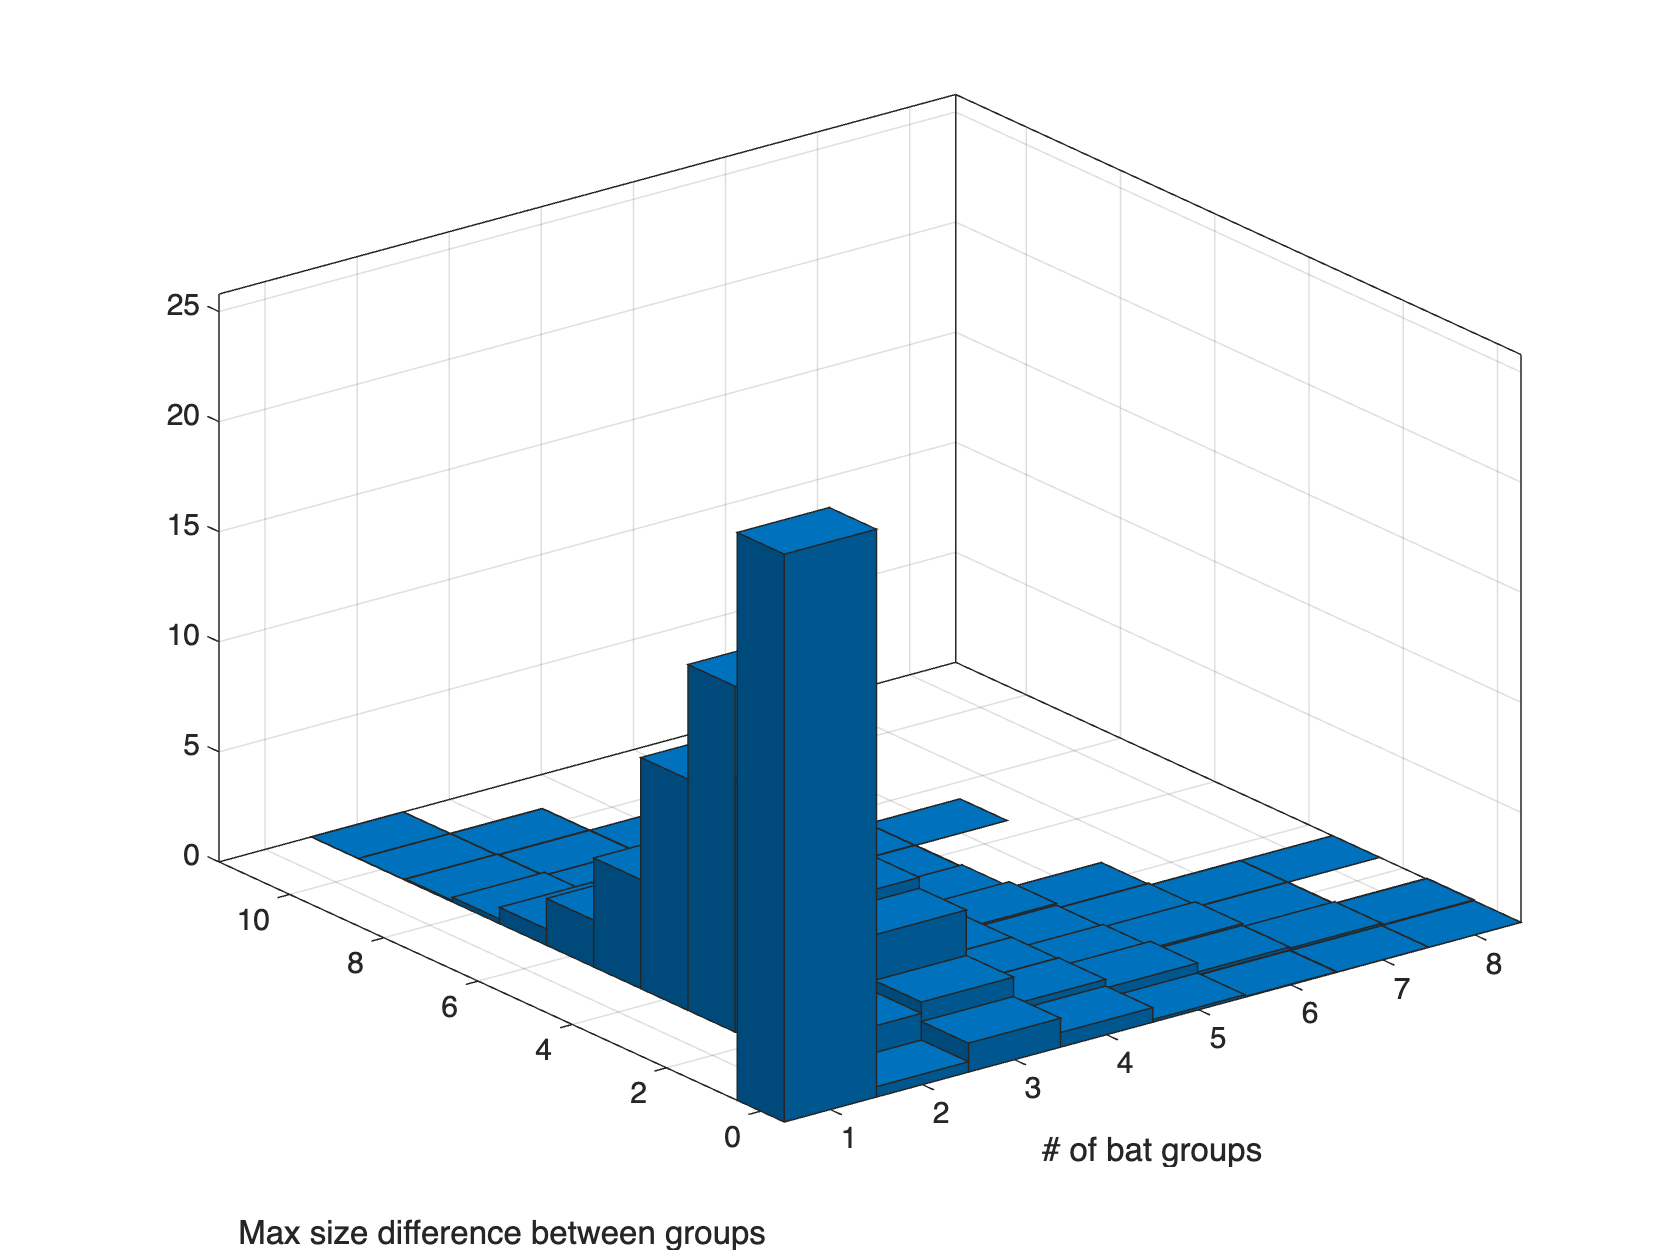

% plot p of numel bat groups vs max diff size
NumGrps = cellfun('length', Clust);
MaxSize = cellfun(@max, Clust);
MinSize = cellfun(@min, Clust);
DiffSize = MaxSize-MinSize;
figure();
histogram2(NumGrps, DiffSize,'Normalization','Percentage')
xlabel('# of bat groups'); ylabel('Max size difference between groups')

fprintf(1, 'In %.f%% of the frames there is only 1 detected group of bats', sum(NumGrps==1)/length(NumGrps)*100)

In 26% of the frames there is only 1 detected group of bats

fprintf(1, 'In %.f%% of the frames there are 2 detected group of bats', sum(NumGrps==2)/length(NumGrps)*100)

In 48% of the frames there are 2 detected group of bats

fprintf(1, 'In %.f%% of the frames there is at least one bat detected as isolated', sum(MinSize==1)/length(NumGrps)*100)

In 73% of the frames there is at least one bat detected as isolated